% First step is to read all the maximum grip force of all the participants

max_force_a01 = 24;
max_force_a02 = 29.4;
max_force_a03 = 24;
max_force_a04 = 31.6;
max_force_a05 = 26.8;
max_force_a06 = 36;
max_force_a07 = 32.2;
max_force_a08 = 21.5;
max_force_a09 = 27.6;
max_force_a10 = 26.1;


max_force_b01 = 63.4;
max_force_b02 = 62.9;
max_force_b03 = 51;
max_force_b04 = 44;
max_force_b05 = 38;
max_force_b06 = 45.7;
max_force_b07 = 48.8;
max_force_b08 = 60;
max_force_b09 = 41.9;
max_force_b10 = 46.7;

% Create two vectors for each group
female_force = [max_force_a01 max_force_a02 max_force_a03 max_force_a04 max_force_a05 max_force_a06 max_force_a07 max_force_a08 max_force_a09 max_force_a10];
male_force = [max_force_b01 max_force_b02 max_force_b03 max_force_b04 max_force_b05 max_force_b06 max_force_b07 max_force_b08 max_force_b09 max_force_b10];

% Perform the mean value of each group
female_mean = mean(female_force)

female_mean = 27.9200

male_mean = mean(male_force)

male_mean = 50.2400

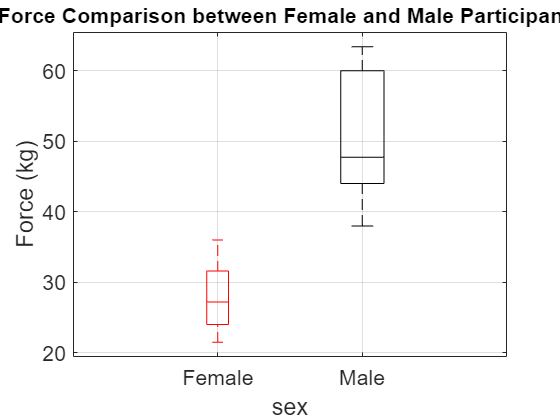

% Plot Box Chart
a = {transpose(female_force),transpose(male_force)};
clear boxchart
figure(1)
boxplotGroup(a, 'PrimaryLabels',{'Female','Male'}, 'Colors','rk')
xlabel('sex','FontSize',16)
ylabel('Force (kg)','FontSize',16)
ax = gca;
ax.FontSize = 16;
grid on
title('Force Comparison between Female and Male Participants','FontSize',16)

% Mann Whitney U Test to test the Hypothesis

[p,h] = ranksum(female_force,male_force)

p = 1.8165e-04

h = logical
   1
